# Esercitazione ONLINE n.1, CN, CdS Informatica, prof. Giulio Giunta

Questo testo è stato creato utilizzando il LIVE EDITOR del Matlab. L'uso è semplice: per inserire una sezione testo o codice Matlab bisogna cliccare sulle rispettive icone (Text, Code) nella barra alta dei comandi. Per interrompere una sezione bisogna cliccare su Section Break. Cliccando su Run si eseguono tutti i comandi Matlab delle sezioni di codice e i risultati sono inseriti nel testo (possono anche apparire in una colonna separata sula destra, basta cliccare su uno dei due pulsantini sulla barra verticale a destra). Usare l'icona Save per salvare le modifiche (o Save as per salvare in un nuovo file). I file creati con LIVE EDITOR hanno estensione .mlx.

### Risoluzione di una equazione

Il problema della risoluzione di una equazione  è indicato con $f(x)=0$; la soluzione $r$ del problema è detta radice dell'equazione oppure zero della funzione $f$. Gli algoritmi (spesso detti metodi) che trattiamo sono metodi iterativi in grado di calcolare una approssimazione di $r$ con una accuratezza richiesta in input. Un algoritmo per $f(x)=0$ è in grado di approssimare una soluzione alla volta. Se la $f$ ha due o più zeri, allora l'algoritmo deve essere applicato due o più volte, indicando ogni volta la soluzione di interesse mediante la scelta di una sua approssimazione iniziale o di un intervallo che la contiene. 

La function Matlab che risolve il problema $f(x)=0$ è `fzero`, che si richiama con due argomenti di input: il primo è l'handle alla function che implementa la $f(x)$, il secondo è una approssimazione iniziale della soluzione oppure un vettore di due componenti che rappresentano l'estremo sinistro e l'estremo destro di un intervallo che contiene la soluzione.

Consideriamo il primo problema dell'esercizio 1 di Lez 2_ter. Si vuole risolvere $0.15x^4-0.5=0$. La funzione è   $f(x) = 0.15x^4-0.5$

La funzione può essere implementata come function anonima, cioè creando direttamente un handle che chiamiamo `f1`

f1 = @(x) 0.15*x.^4-0.5;

In alternativa, si poteva impementare la funzione come function tramite `m-file.`

Si noti l'uso del `.` per indicare che l'operatore `^` deve ssere eseguito seguito componenente per componente, se `x` è un vettore.

Il grafico di $f(x)$ può essere ottenuto con il comando `fplot`, utile quando si vuole visualizzare il grafico di una funzione. L'intervallo scelto e'  $[-2, 2]$ :

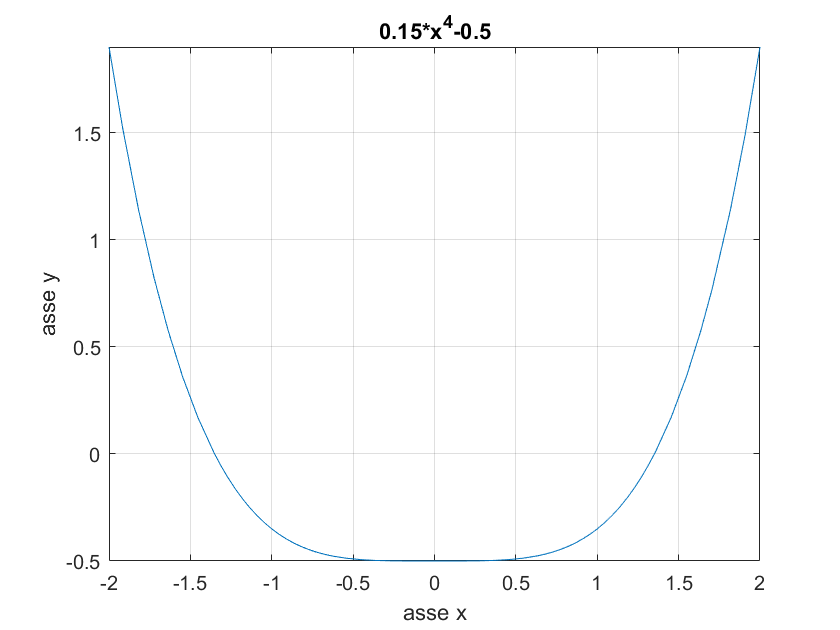

fplot (f1,[-2 2])
title('0.15*x^4-0.5')
xlabel('asse x')
ylabel('asse y')
grid on

Possiamo inserire un testo in una posizione specifica della figura, indicando le coordinate del punto di inserimento

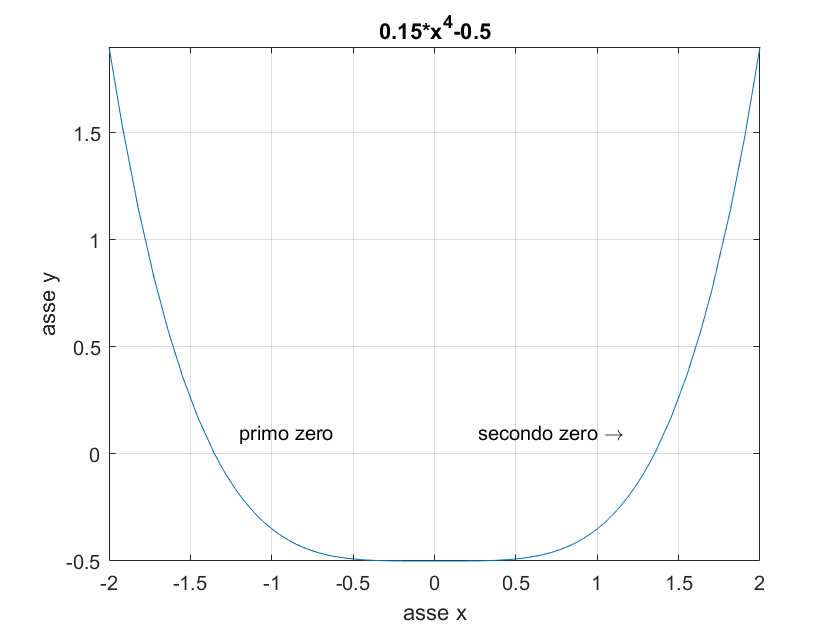


text(-1.2, 0.1, 'primo zero')
text(1.2, 0.1, 'secondo zero \rightarrow ', 'HorizontalAlignment', 'right')

Usando il comando `gtext('testo')` potremmo inserire la stringa `testo` in una qualunque posizione della figura semplicemente posizionando il mouse nella posizione voluta e cliccando con il tasto sinistro.

In alternativa alla `fplot` si può usare `plot`, dopo aver definito una griglia sull'asse delle ascisse e valutato la funzione su tale griglia, ovvero

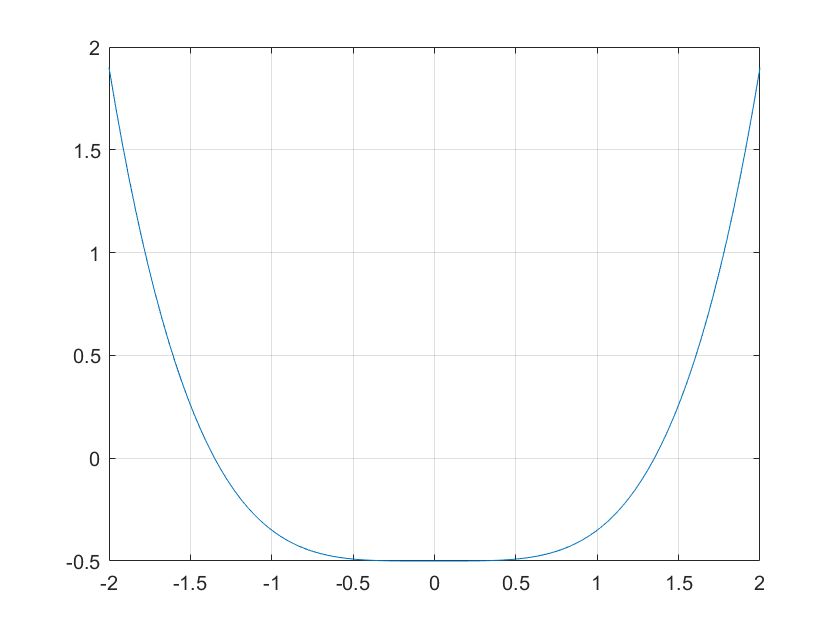

xx =linspace(-2,2,100); 
yy =f1(xx); 
plot(xx,yy)
grid on

Guardando il grafico della $f(x)$ possiamo localizzare due zeri: il primo si trova nell'intervallo $[-1.5, -1]$, il secondo in $[1,1.5]$. Usiamo la function Matlab `fzero` per calcolare il primo zero, che indichiamo con `z1`, con la massima accuratezza possibile (16 cifre)

z1 = fzero(f1,-1.5);
format long
z1

z1 =   -1.351200154807034


`format long` richiede la visualizzazione di tutte le cifre (16) delle variabili numeriche. 

Il secondo zero, che indichiamo con `z2`, può essere calcolato allo stesso modo, passando come approssimazione il valore 1.

z2 = fzero(f1,[1,1.5])

z2 =    1.351200154807034


Calcoliamo il valore che assume la $f$ in `z1` e in `z2`, cioè calcoliamo il cosiddetto **residuo**:

residuo_z1 =  abs(f1(z1))

residuo_z1 =      1.110223024625157e-16


residuo_z2 =  abs(f1(z2))

residuo_z2 =      1.110223024625157e-16


residuo = f1([z1;z2])

residuo = 	1.0e+-15 *

   0.111022302462516
   0.111022302462516


Poiché il problema è ben condizionato (per entrambio gli zeri), i residui sono dello stesso ordine di grandezza dell'errore, cioè dell'ordine di $10^{-16}$, cioè la massima accuratezza possibile nel sistema fp.

Evidenziamo l'asse delle ascisse e gli zeri nel grafico

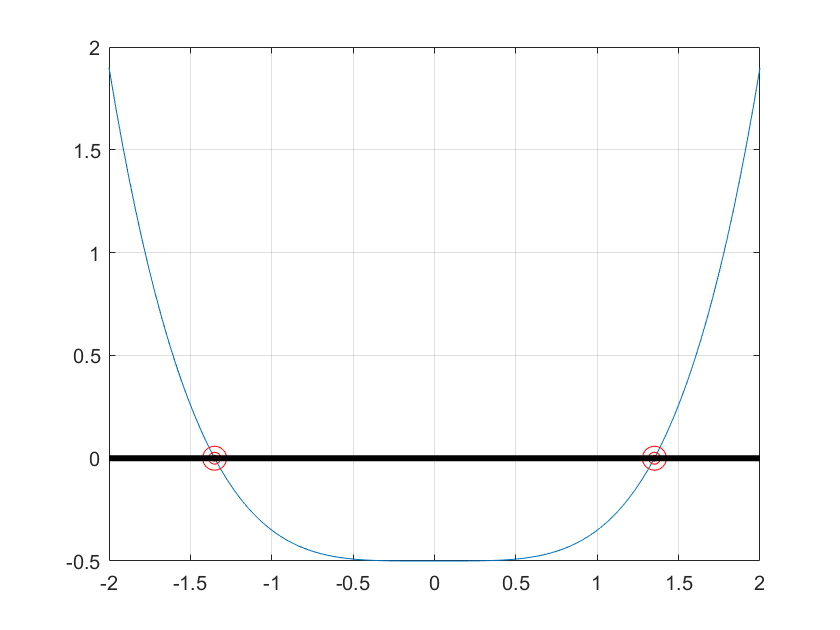

hold on
plot([z1 z2],[0 0],'or')
plot([z1 z2],[0 0],'or','markersize',3)
plot([z1 z2],[0 0],'or','markersize',12)
plot([-2 2],[0 0],'k','linewidth',3)
hold off

### Metodo di Bisezione

Usiamo la function `bisezione` sviluppata nel corso per approssimare il primo zero, con un'accuratezza (errore assoluto) richiesta di $10^{-10}$, cioè almeno 10 cifre della parte frazionaria accurate, calcolando l'errore assoluto e il residuo. Nel calcolo dell'errore assoluto usiamo z1 come valore esatto dello zero. Si noti che l'errore assoluto in generale non è una quantità calcolabile. Nell'esempio noi riteniamo che la soluzione esatta (alla precisione macchina) è quella calcolata da f`zero`

zb1 = bisezione(f1,-1.5,-1,1.e-10)

zb1 =   -1.351200154778780


err_asszb1 = abs(z1-zb1)

err_asszb1 =      2.825406575368561e-11


residuo_zb1 = abs(f1(zb1))

residuo_zb1 =      4.182060253654640e-11


 e il secondo zero, calcolando l'errore assoluto e il residuo

zb2 = bisezione(f1,1,1.5,1.e-10)

zb2 =    1.351200154778780


err_asszb2 = abs(z2-zb2)

err_asszb2 =      2.825406575368561e-11


residuo_zb2 = abs(f1(zb2))

residuo_zb2 =      4.182060253654640e-11


Poiché il problema è ben condizionato (per entrambio gli zeri), i residui sono dello stesso ordine di grandezza dell'errore, cioè dell'ordine di $10^{-11}$, minore dell'accuratezza richiesta $10^{-10}$.

Passiamo al calcolo dell'errore assoluto di `bisezione`, relativamente al primo zero, al variare dell'accuratezza richiesta da $10^{-1}$ a  $10^{-14}$

err_assB=zeros(14,1);
for i = 1:14
     zb = bisezione(f1,-1.5,-1,10^(-i));
     err_assB(i) = abs(zb-z1);
end

L'andamento dell'errore assoluto è visualizzato prima su scala semilogaritmica per le ordinate e poi su scala logaritmica

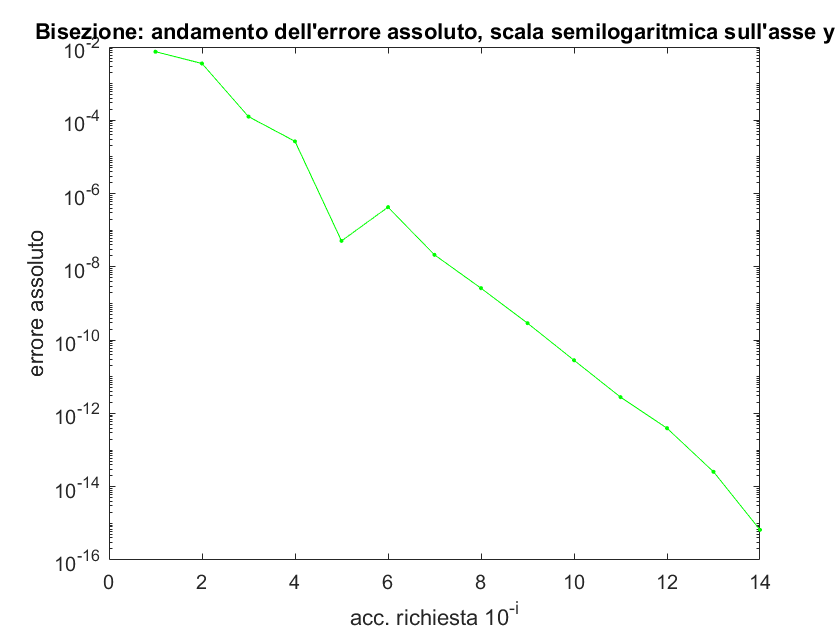

figure(2)
semilogy(1:14,err_assB,'.-g')
title('Bisezione: andamento dell''errore assoluto, scala semilogaritmica sull''asse y')
xlabel('acc. richiesta 10^-^i')
ylabel('errore assoluto')

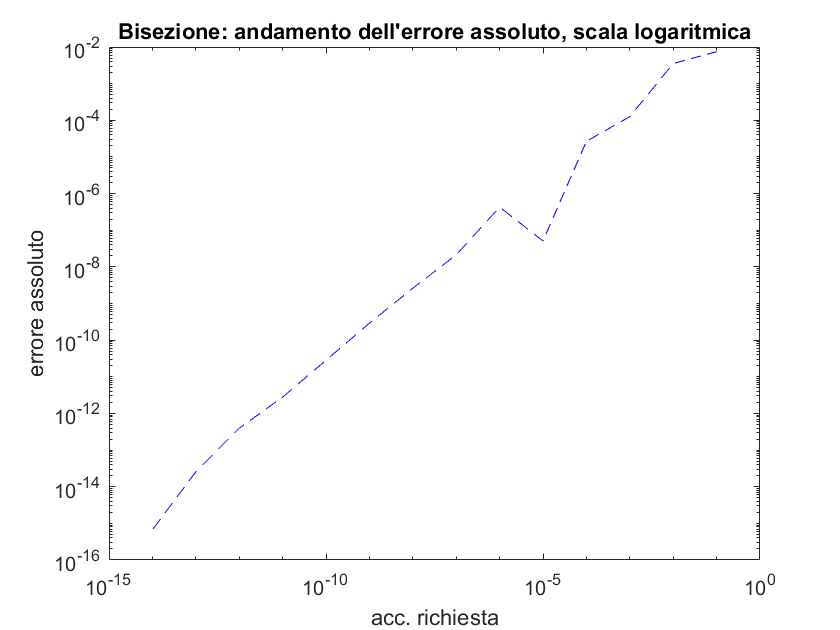


figure(3) 
loglog(10.^(-1:-1:-14),err_assB,'--b')
title('Bisezione: andamento dell''errore assoluto, scala logaritmica')
xlabel('acc. richiesta')
ylabel('errore assoluto')

Il comando `funtool` consente di utilizzare in modo semplice le potenzialità del symbolic toolbox di Matlab. E' molto utile per calcolare l'espressione esplicita di derivate e integrali indefiniti di funzioni. Ricordare che l'espressione di una funzione deve essere nel formato matematico classicio (non si deve usare .*, .^, etc. come nelle espressioni Matlab)

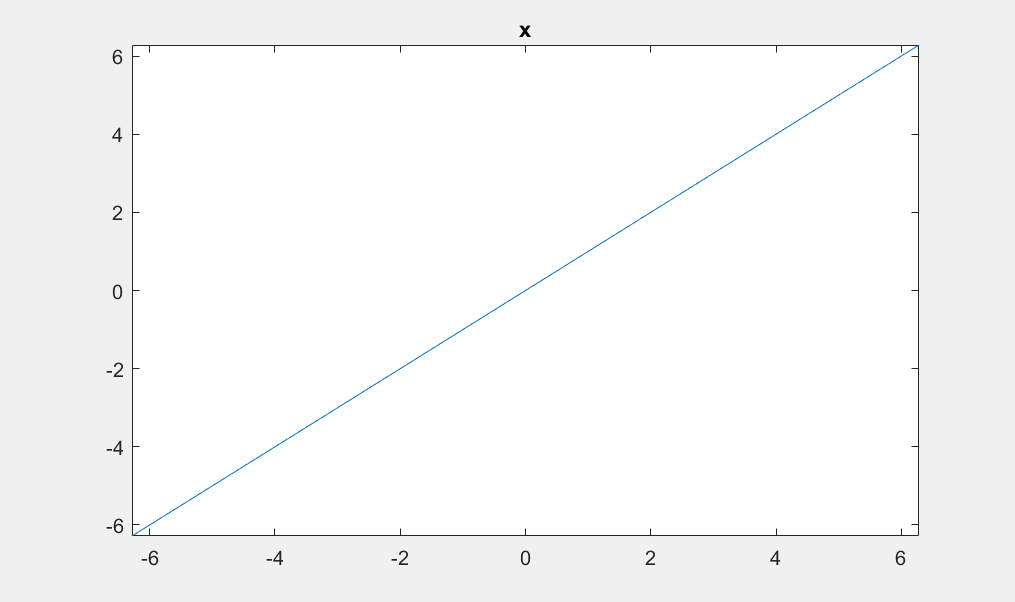

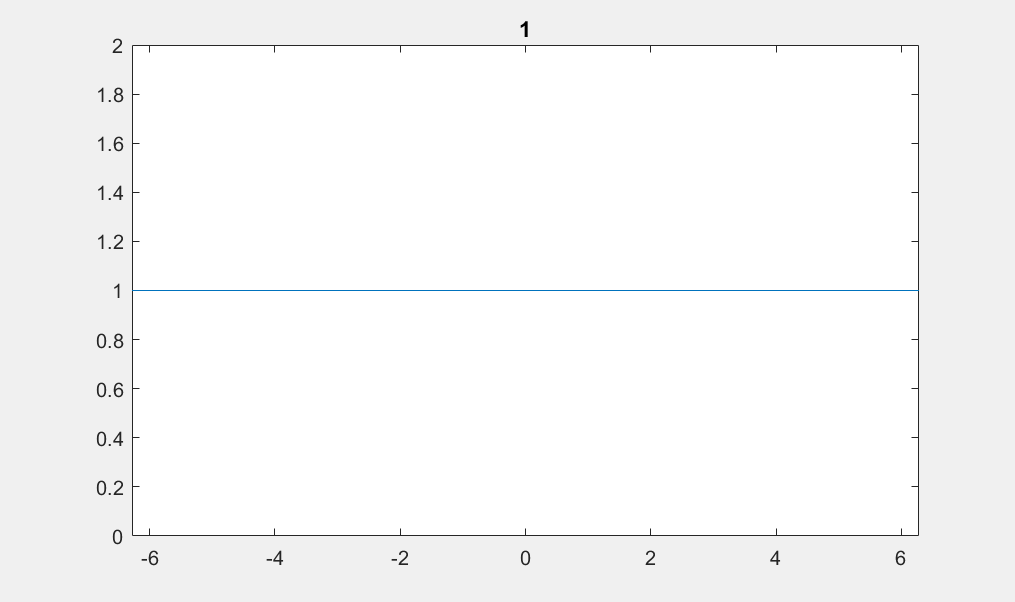

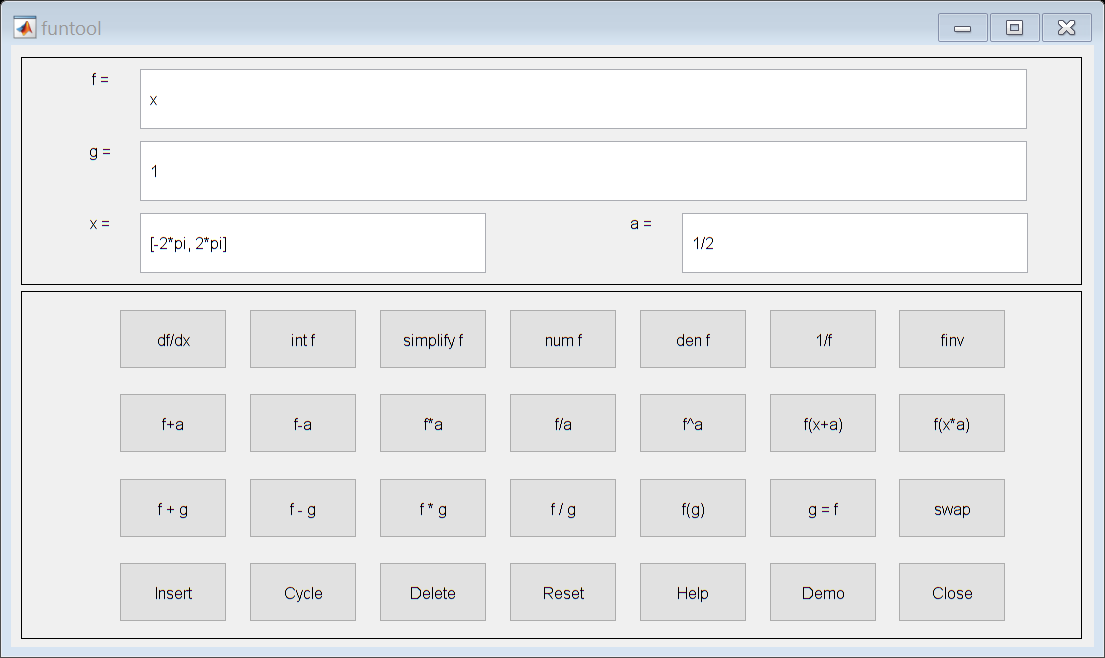

funtool

Modificando l'espressione della f nell'apposito riquadro f= (dove appare ora x) , si ottiene il grafico della f nell'intervallo indicato nel riquadro x= (dove ora appare [-2*pi,2*pi] ). Cliccando sul pulsante df/dx si ottiene l'espressione della derivata della funzione.

### Metodo di Newton

Usiamo la function `Newton` sviluppata nel corso per approssimare il primo zero della funzione  $f(x) = 0.15x^4-0.5$, con un'accuratezza (errore assoluto) richiesta di $10^{-10}$, cioè almeno 10 cifre della parte frazionaria accurate, calcolando l'errore assoluto e il residuo. Nel calcolo dell'errore assoluto si usa z1 come valore esatto dello zero.

Per usare la function `Newton` bisogna definire una function, che chiameremo `f1primo`, che implementa la funzione $f'(x)$ . In questo caso l'espressione della derivata è semplicissima. In casi più complessi è utile utilizzare `funtool.`

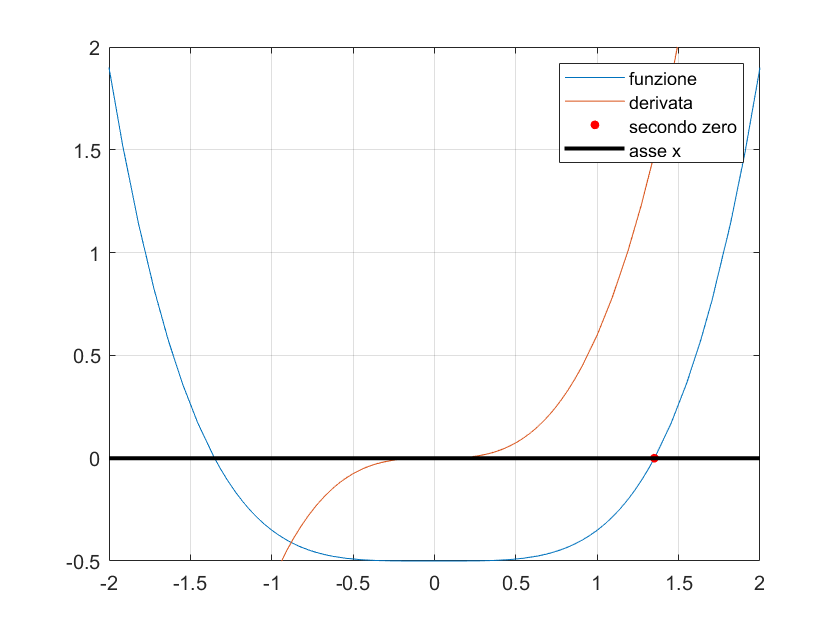

f1primo = @(x) 0.6*x.^3;
figure (4)
fplot(f1,[-2 2])
hold on
fplot(f1primo,[-2 2])
grid on
plot([z2],[0],'.r','markersize',15)
plot([-2 2],[0 0],'k','linewidth',2)
legend('funzione','derivata','secondo zero','asse x')
axis([-2 2 -0.5 2])
hold off

Il comando `axis([-2 2 -0.5 2])` defisce i limiti sull'asse $x$, cioè -2 ,2, e sull'asse $y$, cioè -0.5, 2, della figura.

Nella variabile` zn1` viene memorizzata l'approssimazione della soluzione calcolata con il metodo di Newton con un'accuratezza richiesta di $10^{-10}$

zn1 = Newton(f1,f1primo,-1.5,1e-10,20)

zn1 =   -1.351200154807098


err_asszn1 = abs(zn1-z1)

err_asszn1 =      6.350475700855895e-14


residuo_zn1 = abs(f1(zn1))

residuo_zn1 =      9.414691248821327e-14


Passiamo al calcolo dell'errore assoluto di Newton, relativamente al primo zero, al variare dell'accuratezza richiesta da $10^{-1}$ a  $10^{-14}$. L'andamento dell'errore assoluto è visualizzato prima su scala semilogaritmica per le ordinate e poi su scala logaritmica

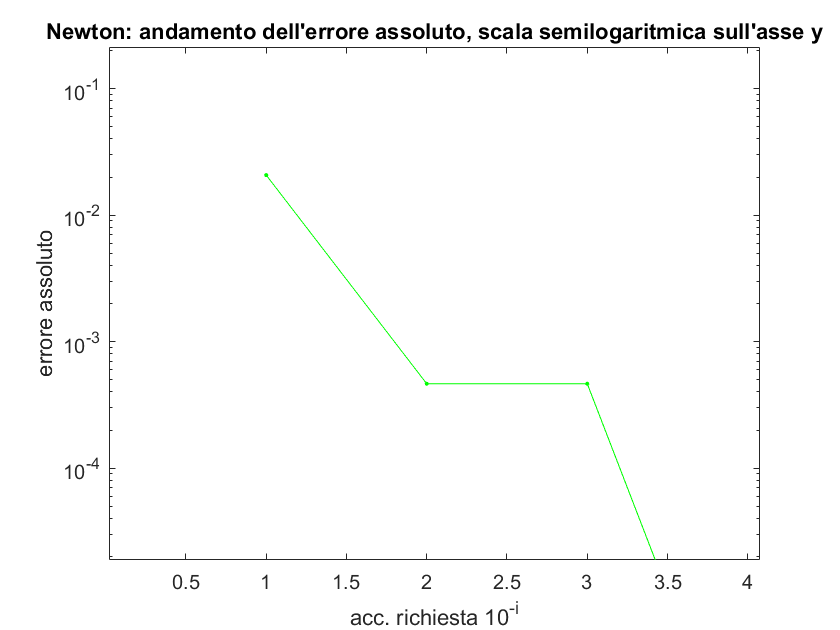

err_assN = zeros(14,1);
for i=1:14
      zN = Newton(f1,f1primo,-1.5,10^(-i),20);
      err_assN(i) = abs(zN-z1);
end
figure(5)
semilogy(1:14,err_assN,'.-g')
title('Newton: andamento dell''errore assoluto, scala semilogaritmica sull''asse y')
xlabel('acc. richiesta 10^-^i')
ylabel('errore assoluto')

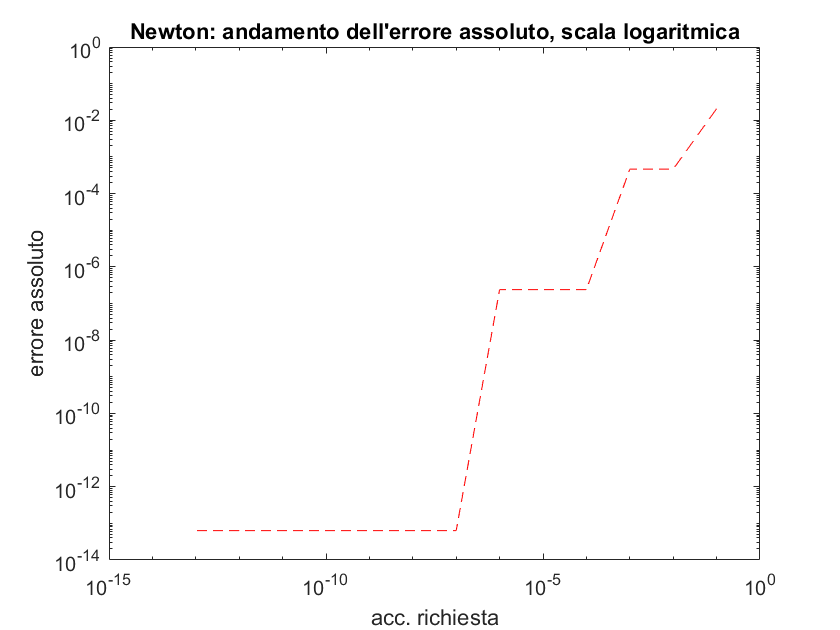

figure(6)
loglog(10.^(-1:-1:-14),err_assN,'--r')
title('Newton: andamento dell''errore assoluto, scala logaritmica')
xlabel('acc. richiesta')
ylabel('errore assoluto')

### Metodo delle Secanti

Usiamo la function `Secanti` sviluppata nel corso per approssimare lo zero della funzione  $f(x) = \frac{x^3-2x^2+x}{x^2-1}$ nell'intervallo $[0.2,1,5]$ con un'accuratezza (errore assoluto) richiesta di $10^{-6}$, cioè almeno 6 cifre della parte frazionaria accurate, calcolando l'errore assoluto e il residuo. Nel calcolo dell'errore assoluto si usa come valore esatto dello zero quello restituito dalla `fzero`

f4 = @(x) (x.^3-2*x.^2+x)./(x.^2-1) ;
z4 = fzero(f4,[0.2,1.5])

z4 =    0.999999999189368


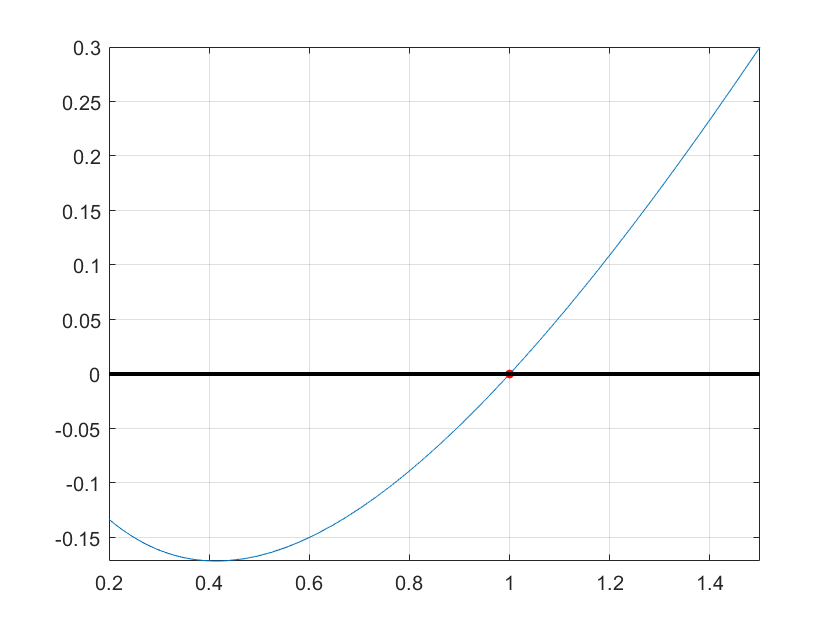

figure(7)
fplot(f4,[0.2,1.5])
grid on
hold on
plot(z4,0,'.r','markersize',15)
plot([0.2 1.5],[0 0],'k','linewidth',2)
hold off

Nella variabile` zs4` viene memorizzata l'approssimazione della soluzione calcolata con il metodo delle Secanti  con un'accuratezza (errore assoluto) richiesta di $10^{-6}$

zs4 = Secanti(f4,0.5,0.6,1e-6,20)

zs4 =    0.999999962792295


err_asszs4 = abs(zs4-z4)

err_asszs4 =      3.639707324420982e-08


residuo_zs4 = abs(f4(zs4))

residuo_zs4 =      1.939504144460762e-08


Passiamo al calcolo dell'errore assoluto delle Secanti al variare dell'accuratezza richiesta da $10^{-1}$ a  $10^{-10}$. L'andamento dell'errore assoluto è visualizzato prima su scala semilogaritmica per le ordinate e poi su scala logaritmica

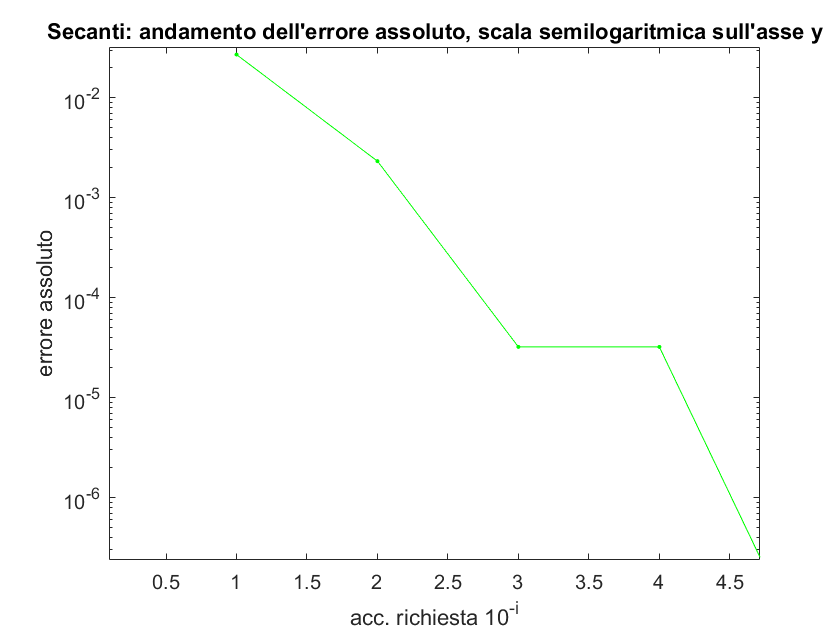

err_assS = zeros(10,1);
for i=1:10
      zS = Secanti(f4,0.5,0.6,10^(-i),40);
      err_assS(i) = abs(zS-z4);
end
figure(8)
semilogy(1:10,err_assS,'.-g')
title('Secanti: andamento dell''errore assoluto, scala semilogaritmica sull''asse y')
xlabel('acc. richiesta 10^-^i')
ylabel('errore assoluto')

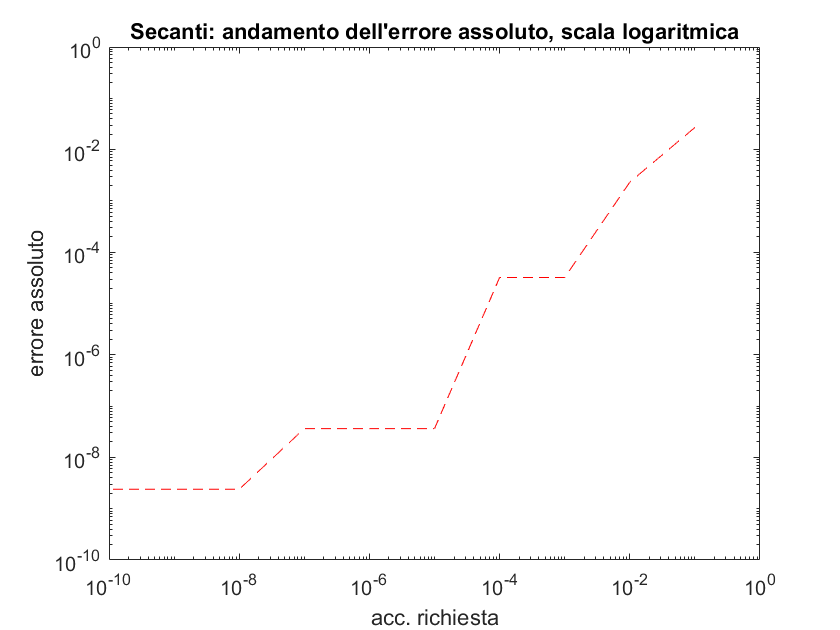

figure(9)
loglog(10.^(-1:-1:-10),err_assS,'--r')
title('Secanti: andamento dell''errore assoluto, scala logaritmica')
xlabel('acc. richiesta')
ylabel('errore assoluto')

Consideriamo l'esercizio 3 di LEZ2_ter, cioè calcoliamo gli zeri della funzione $f(x)=e^{-cos(3x)}(x^2-3x)+1$ nell'intervallo $[0, \pi]$

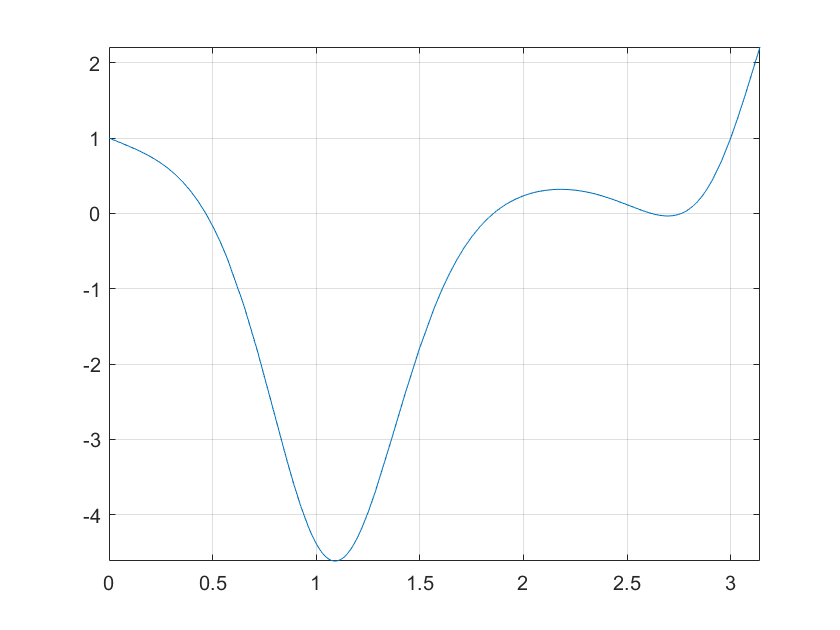

f = @(x) exp(-cos(3*x)).*(x.^2-3*x)+1;
figure(10)
fplot(f,[0,pi]), grid on

La funzione ha quattro zeri nell'intervallo di interesse. Per calcolarli è necessario richiamare quattro volte la `fzero`

figure(11)
fplot(f,[0,pi]), grid on
hold on
plot([0 pi],[0 0],'k')
solM = [];
for xzero = [0.5, 2, 2.5 3]
solM = [solM fzero(f,xzero)];
end
disp('I quattro zeri della funzione sono:')

I quattro zeri della funzione sono:


solM

solM =    0.467213320722246   1.855124897932551   2.617876585228863   2.761254930917656


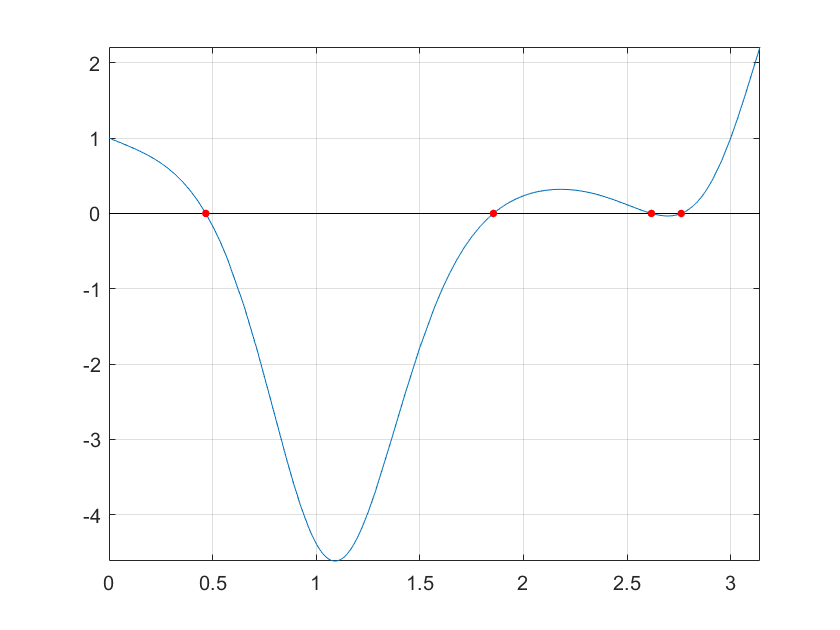

plot(solM,f(solM),'.r','markersize',13)
hold off

residui = abs(f(solM))

residui = 	1.0e+-15 *

   0.222044604925031   0.111022302462516   0.888178419700125                   0


Usiamo la function `NewtonGlobale` che implementa un metodo ibrido Newton-Bisezione per calcolare i due zeri del polinomio $x^2-4x+3.5$

fpol = @(x) x.^2-4*x+3.5;
figure(12)
fplot(fpol,[1,3])
zpol1 = fzero(fpol,[1,1.8])

zpol1 =    1.292893218813452


zpol2 = fzero(fpol,[2.5,3])

zpol2 =    2.707106781186548


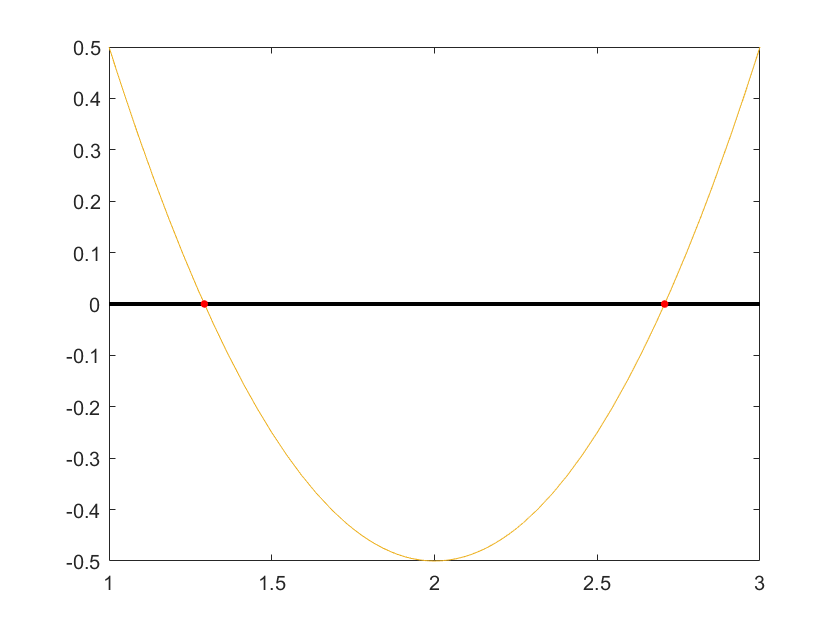

hold on
plot([1,3],[0,0],'k','LineWidth',2)
plot([zpol1, zpol2],[0,0],'.r','Markersize',13)

derfpol = @(x) 2*x-4;
zNGpol1 = NewtonGlobale(fpol,derfpol,1.,2.5,1e-10,1e-10,30)

   1.000000000000000     2.455889172640924       2.500000000000000
Bisezione
   1.000000000000000     1.750000000000000       1.750000000000000
Bisezione
   1.000000000000000     1.375000000000000       1.375000000000000
Newton
   1.287500000000000     1.287500000000000       1.375000000000000
Newton
   1.292872807017544     1.292872807017544       1.375000000000000
Newton
   1.292893218518851     1.292893218518851       1.375000000000000
Newton
   1.292893218518851     1.292893218813453       1.292893218813453


zNGpol1 =    1.292893218813453


zNGpol2 = NewtonGlobale(fpol,derfpol,2.2,2.8,1e-10,1e-10,30)

   2.200000000000000     2.774300168945767       2.800000000000000
Newton
   2.200000000000000     2.710022285754181       2.710022285754181
Newton
   2.200000000000000     2.707112767031678       2.707112767031678
Newton
   2.200000000000000     2.707106781211883       2.707106781211883


zNGpol2 =    2.707106781211883


Se la funzione è un polinomio, Matlab ha la function specializzata `roots` per calcolare **tutti **gli zeri. In Matlab un polinomio è rappresentato mediante un vettore che contiene i coefficienti in ordine delle potenze decrescenti. Quindi il polinomio $x^2-4x+3.5$  è rappresentato dal vettore `[1, -4, 3.5]`.

zpol = roots([1 -4 3.5])

zpol =    2.707106781186547
   1.292893218813453
